# Linear and quadratic discriminants

If we model each class by a multivariate Gaussian distribution, then the best discriminant will be either linear or quadratic.

Set the prior probabilities of each of the two classes.

p1  = 0.5;
p2  = 1 - p1;

Set the means of the two classes.

mu1 = [-4; 0];
mu2 = [4; 0];

We'll look at several cases.

Sigma1  = [2 -1; -1 2]

Sigma1 =      2    -1
    -1     2


Sigma2  = [2 -1; -1 2]

Sigma2 =      2    -1
    -1     2


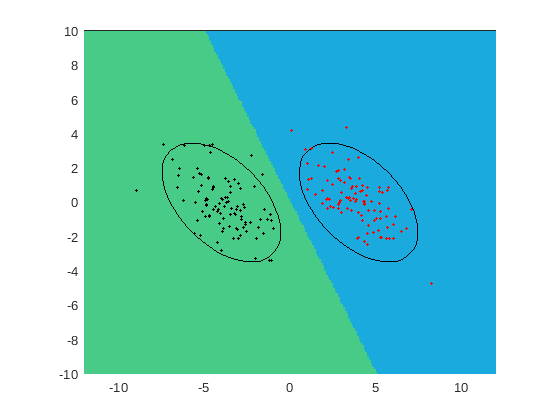

plot_discriminant(mu1, mu2, Sigma1, Sigma2, p1, p2);


Sigma1  = [1  0;  0 1]

Sigma1 =      1     0
     0     1


Sigma2  = [2  1;  1 2]

Sigma2 =      2     1
     1     2


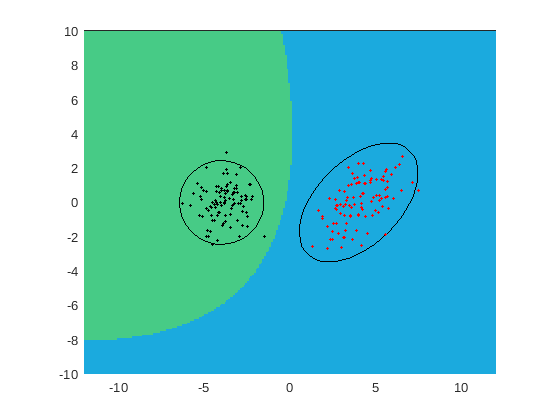

plot_discriminant(mu1, mu2, Sigma1, Sigma2, p1, p2);


Sigma1  = [.1  0;  0 2]

Sigma1 =     0.1000         0
         0    2.0000


Sigma2  = [2  0;  0 .1]

Sigma2 =     2.0000         0
         0    0.1000


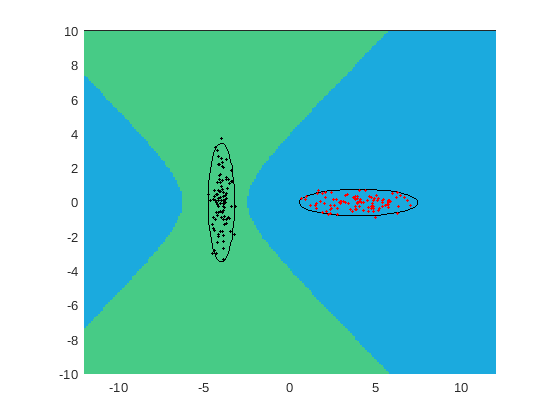

plot_discriminant(mu1, mu2, Sigma1, Sigma2, p1, p2);


Sigma1  = [2 -1; -1 2]

Sigma1 =      2    -1
    -1     2


Sigma2  = [2  1;  1 2]*0.1

Sigma2 =     0.2000    0.1000
    0.1000    0.2000


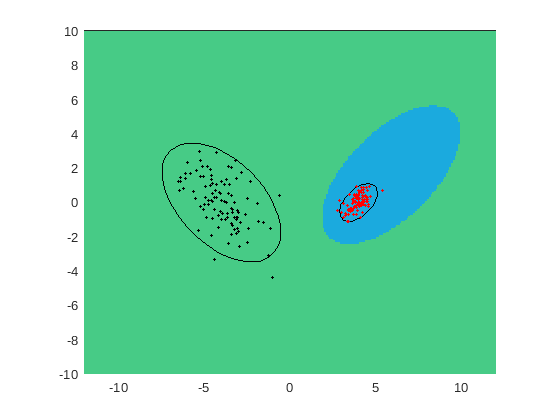

plot_discriminant(mu1, mu2, Sigma1, Sigma2, p1, p2);


Sigma1  = [1  0;  0 1]

Sigma1 =      1     0
     0     1


Sigma2  = [1  0;  0 1]*0.2

Sigma2 =     0.2000         0
         0    0.2000


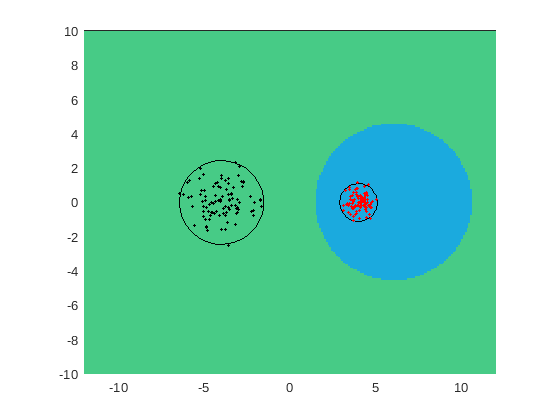

plot_discriminant(mu1, mu2, Sigma1, Sigma2, p1, p2);


Sigma1  = [2 -1; -1 2]

Sigma1 =      2    -1
    -1     2


Sigma2  = [2  1;  1 2]

Sigma2 =      2     1
     1     2


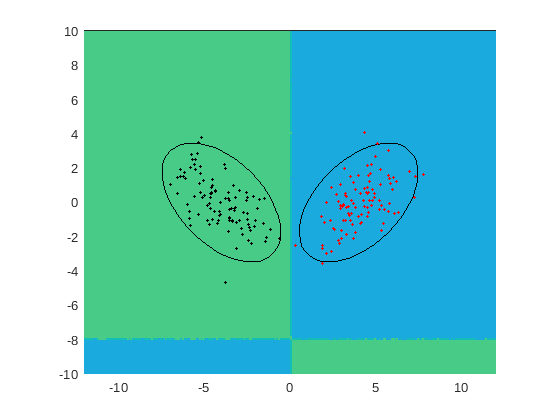

plot_discriminant(mu1, mu2, Sigma1, Sigma2, p1, p2);

The following function computes and plots the discriminant function corresponding to two classes, each modeled with a Gaussian distribution.

function plot_discriminant(mu1, mu2, Sigma1, Sigma2, p1, p2)

% compute values of the discriminant function on a mesh
xx = -12:.1:12;
yy = -10:.1:10;
Z = zeros(length(yy),length(xx));
invSigma1 = inv(Sigma1);
invSigma2 = inv(Sigma2);
logdetSigma1 = 0.5*log(det(Sigma1));
logdetSigma2 = 0.5*log(det(Sigma2));
for i = 1:length(xx)
for j = 1:length(yy)
  x = [xx(i); yy(j)];
  Z(j,i) = -logdetSigma1 -0.5*(x-mu1)'*invSigma1*(x-mu1) ...
           +logdetSigma2 +0.5*(x-mu2)'*invSigma2*(x-mu2) ...
           + log(p1) - log(p2);
end
end

% plot sign of discriminant function
clf
h = pcolor(xx,yy,sign(Z));
set(h, 'edgecolor', 'none');
caxis([-5 5]);
axis equal
axis tight
hold on

% plot ellipses
plot_ellipse95(mu1, Sigma1);
plot_ellipse95(mu2, Sigma2);

% plot sample data
r = mvnrnd(mu1, Sigma1, 100);
scatter(r(:,1),r(:,2),5,'k','filled');
r = mvnrnd(mu2, Sigma2, 100);
scatter(r(:,1),r(:,2),5,'r','filled');
end

The following function plots the 95% confidence ellipse for a Gaussian distribution.

function plot_ellipse95(mu, Sigma)
[V D] = eig(Sigma);
theta = linspace(0, 2*pi, 50)';
pointsx = sqrt(5.9912*D(1,1))*cos(theta);
pointsy = sqrt(5.9912*D(2,2))*sin(theta);
angle = atan(V(2,1)/V(1,1));
R = [cos(angle) sin(angle); -sin(angle) cos(angle)];
points = [pointsx pointsy] * R;
plot(points(:,1)+mu(1), points(:,2)+mu(2), 'k');
end